# Example 6.19: Applying 2D Filters to a Micrograph

Note: this script complements Example 6.19 (Section 6.3.5) of **Statistics for Chemical Engineers**: Sobel and Gaussian filters applied to a micrograph. Victor Z UW-Madison, 2020 use filters on micrograph

clc; clear all; close all hidden

## Image

reading and converting the image

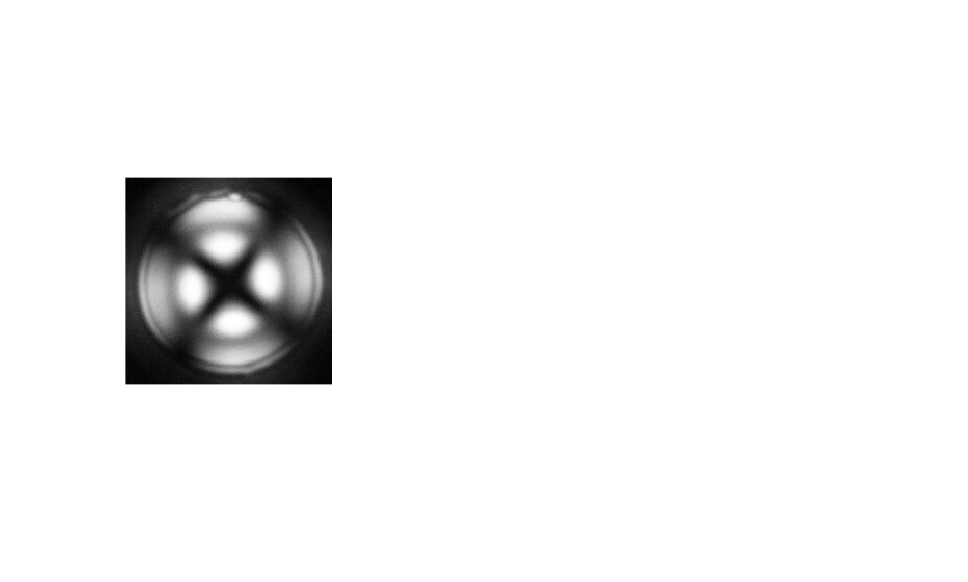

inImage=imread('./Data/droplet1.jpg');
inImage=rgb2gray(inImage);
f=double(inImage); 

figure(1)
subplot(1,3,1)
imshow(uint8(f),[]);
box off

## Sobel filter

apply Sobel filter in vertical direction

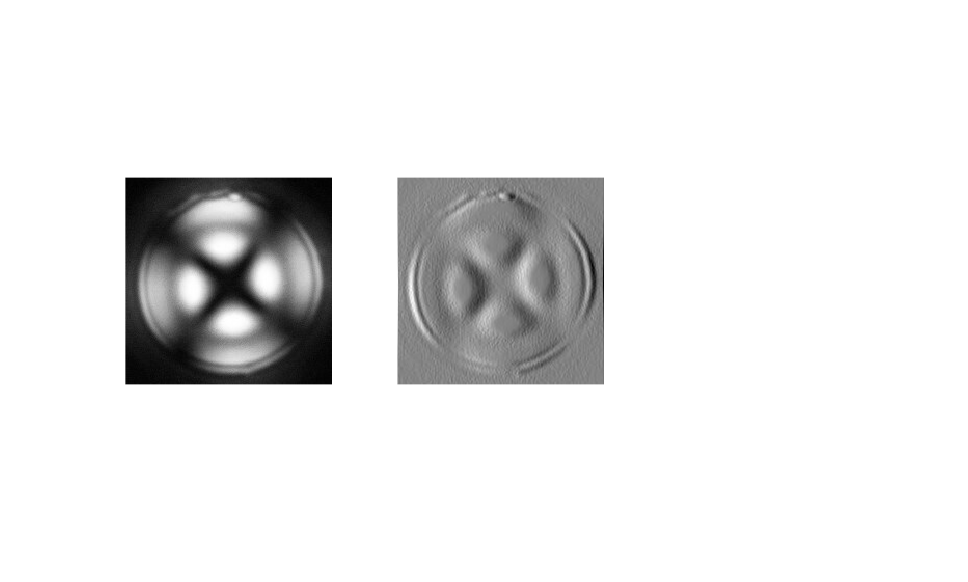

g=[1 2 1; 
   0 0 0; 
   -1 -2 -1]';

fsob=conv2(f,g,'same');

subplot(1,3,2)
imshow(mat2gray(fsob));
box off

## Gaussian filter

apply Gaussian filter using convolution

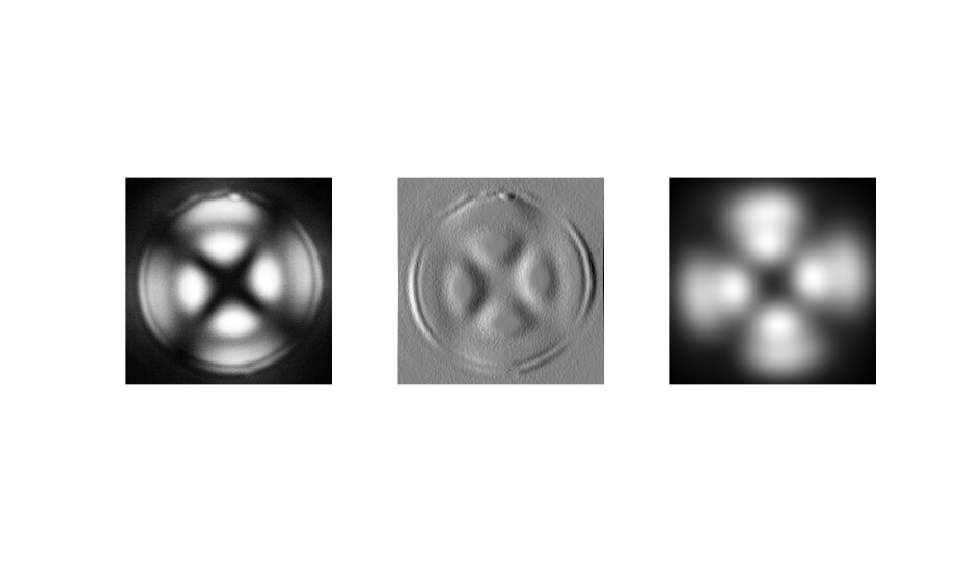

%subplot(2,2,3)
%imshow(mat2gray(f));
%box off

sigma=10;
hsize=length(f);
g = fspecial('gaussian',hsize,sigma);

fn=conv2(f,g,'same');

%fn=ifft2(fft2(f).*fft2(g));
%fn=real(fftshift(fn));

subplot(1,3,3)
imshow(mat2gray(fn));
box off

print -depsc ch6_micrograph_2Dfilters.eps

## Note

Filters highlight features of an image (edges) or remove details (smoothing), depending on their design.